clear; 
clc; 
close all;

rng(3); 

% Load Bus Object definitions
UtilityBus; 

Creating and loading System Bus definitions...
All System Bus definitions have been created and loaded.



% Load scenario data
data = load('GlobalRoutePlan.mat');
routePlan = data.routePlan;

costmap = createParkingLotCostmap();
outputData = createSimulinkStructs(costmap); 
vehicleDimsStruct = outputData{1};
costmapStruct     = outputData{2};

outputData = createSimulinkStructs(costmap); 
vehicleDimsObject_for_Plotting = costmap.CollisionChecker.VehicleDimensions;

% Prepare configurations and initial setup
initialPose = routePlan.StartPose(1, :);
initialSpeed = 0;

plannerRRTConfig.MinTurningRadius = 4.0;
plannerRRTConfig.ConnectionDistance = 30.0;
plannerRRTConfig.GoalTolerance = [0.5 0.5 10];
plannerRRTConfig.MinIterations = 2000;

speedConfig.StartSpeed = 0;
speedConfig.EndSpeed   = 0;
speedConfig.MaxSpeed   = 1.5;

% --- STEP 2: CALCULATION OF THE DETAILED TACTICAL PATH (RRT*) ---
% Creation of the RRT* planner object (the global planner)
motionPlannerRRT = pathPlannerRRT(costmap, ...
    'ConnectionDistance', plannerRRTConfig.ConnectionDistance, ...
    'MinIterations',      plannerRRTConfig.MinIterations, ...
    'GoalTolerance',      plannerRRTConfig.GoalTolerance, ...
    'MinTurningRadius',   plannerRRTConfig.MinTurningRadius);

fprintf('Calculation of the tactical path with RRT*...\n');

Calculation of the tactical path with RRT*...


globalWaypoints = []; 
initialPose = routePlan{1, 'StartPose'};
finalGoal = routePlan{end, 'EndPose'};

for i = 1:height(routePlan)
    fprintf('  - Segment planning %d...\n', i);
    
    startPose = routePlan{i, 'StartPose'};
    endPose   = routePlan{i, 'EndPose'};
    
    % Use the RRT* planner to find a collision-free path
    segmentPathObject = plan(motionPlannerRRT, startPose, endPose);
    
    % Interpolate the path to obtain a dense series of points
    segmentPoses = interpolate(segmentPathObject);
    
    if isempty(segmentPoses)
        error('RRT* was unable to find a path for the segment %d.', i);
    end
    
    % Concatenate the paths of the segments, avoiding duplicating points.
    if i == 1
        globalWaypoints = [globalWaypoints; segmentPoses];
    else
        globalWaypoints = [globalWaypoints; segmentPoses(2:end, :)];
    end
end

  - Segment planning 1...
  - Segment planning 2...
  - Segment planning 3...
  - Segment planning 4...
  - Segment planning 5...



fprintf('Global tactical path with %d waypoints successfully created!\n', size(globalWaypoints, 1));

Global tactical path with 21 waypoints successfully created!


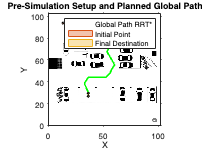


% --- STEP 3: VISUALIZATION AND SETUP FOR SIMULINK ---

% Scene preview for visual inspection
figure;
plot(costmap, 'Inflation', 'off');
hold on;
plot(globalWaypoints(:,1), globalWaypoints(:,2), 'g-', 'LineWidth', 2, 'DisplayName', 'Global Path RRT* ');
PlotBicycle(initialPose, vehicleDimsObject_for_Plotting, 'DisplayName', 'Initial Point');
PlotBicycle(finalGoal, vehicleDimsObject_for_Plotting, 'DisplayName', 'Final Destination');
legend;
title('Pre-Simulation Setup and Planned Global Path');
hold off;


modelName = 'STANLEY';

